# Digital Signal Processing Lab 6

### Syed Asghar Abbas Zaidi 07201

#### Task 1

In the provided code snippet, we define parameters for simulating a quantization process using Delta Modulation (DM). These parameters include amplitudes, frequencies, oversampling factor, sampling frequency, and quantization bits. We then generate a continuous sine wave signal composed of two tones based on these parameters. After sampling the signal at a specified frequency, we quantize the sampled signal using a quantization function, restricting its values to a finite set of levels determined by the number of quantization bits. Finally, we plot both the original continuous signal and the quantized signal on the same graph for comparison, showcasing the effects of quantization on the signal's fidelity.

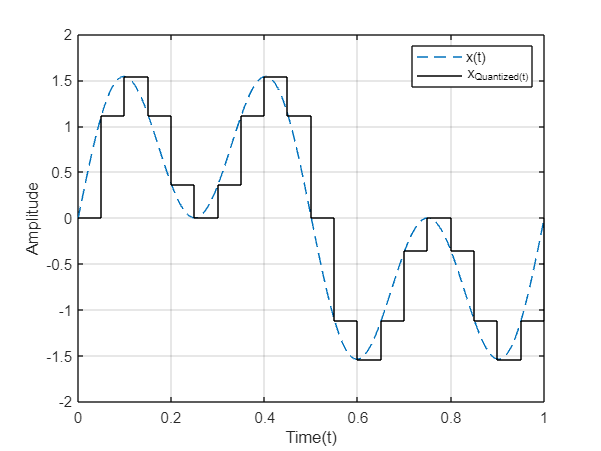

clear all; close all; clc;
% Defining the Parameters
 A1 = 1;A3 = 1;f1 = 1;f3 = 3;
 K = 20/3;
 fs = K*f3;
 B = 8;
 % Deciding the time vector for each cycle!
 t = 0:0.002:1;
 %Producing the sine wave
 x = A1*sin(2*pi*f1*t) + A3*sin(2*pi*f3*t);
 ts= 0:1/fs:1;
 xs = A1*sin(2*pi*f1*ts) + A3*sin(2*pi*f3*ts);
 % Quantize the sampled signal
 X_Q = quantize(xs,B);
 % Plot the continuous signal and the quantized signal
 
 figure;
 plot(t, x, '--');
 hold on;
 stairs(ts, X_Q, 'k-');
 hold off;
 % Display the plot
 grid on;
 xlabel('Time(t)');
 ylabel('Amplitude');
 legend("x(t)","x_Quantized(t)");

#### Task 2

In this code snippet, we apply oversampling to the quantized signal  obtained from Delta Modulation (DM) by repeating each quantized level  multiple times, determined by the oversampling factor L. This  oversampled signal is then subjected to a Fast Fourier Transform (FFT)  to analyze its frequency components. To ensure accurate frequency  representation, we scale the FFT result by the computer simulation  sampling time, which is inversely proportional to the oversampling  frequency. Finally, we plot the absolute FFT values against the  frequency axis, providing insights into the frequency content of the  oversampled signal, with the frequency axis scaled appropriately to  reflect the oversampling factor.

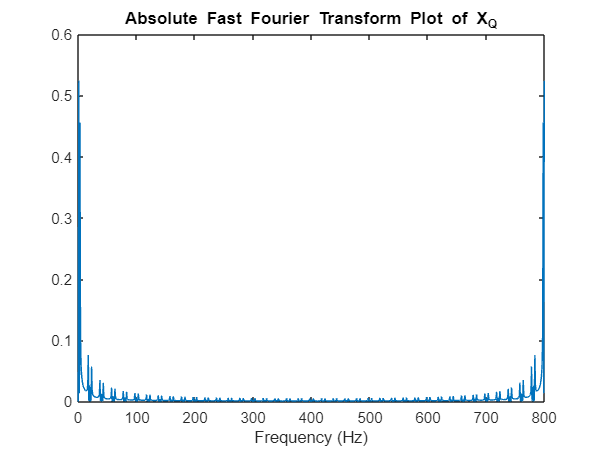

% Setting oversampling factor
L = 40;

% Repeating each quantized level L times
X_Q = repmat(X_Q, L, 1); 
X_Q = X_Q(:);

% Performing FFT on the oversampled signal
X_Q = fft(X_Q);

% Calculating the computer simulation sampling time
csst = 1/(L*fs);

% Scaling FFT result with the sampling time
X_Q = X_Q*csst;

% Creating frequency axis
F_Axis = linspace(0, fs*L, length(X_Q));

% Plotting the absolute FFT
plot(F_Axis,abs(X_Q));

% Adding title and axis labels
title("Absolute Fast Fourier Transform Plot of X_Q");
xlabel("Frequency (Hz)");

#### Task 2 (cont.)

This code segment visualizes the absolute values of the Fast Fourier Transform (FFT) of the oversampled signal using a stem plot. By specifying markers as 'none', it ensures that no markers are displayed on the stems. The y-axis limits are set to ensure that the plot's details are visible, restricting it to a range from 0 to 0.6. Similarly, the x-axis limits are set from 0 to 70 Hz to focus on the relevant frequency range. Lastly, the plot is titled "Absolute Fast Fourier Transform Plot of X_Q", with appropriate labels for both axes denoting frequency in Hertz.

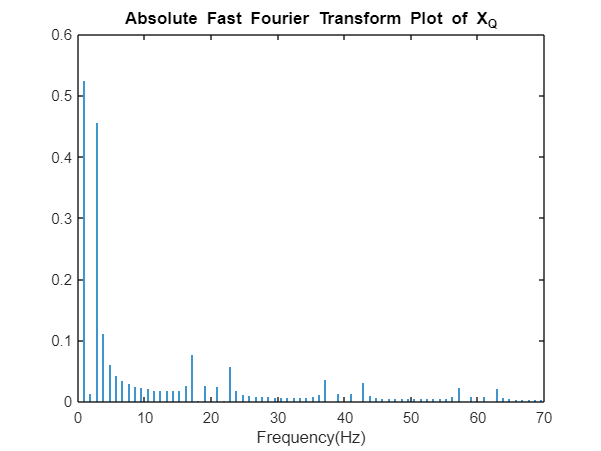

% Plotting the absolute FFT using stem plot
stem(F_Axis, abs(X_Q), 'Marker', 'none');

% Setting y-axis limits
ylim([0 0.6]);

% Setting x-axis limits
xlim([0 70]);

% Adding title and axis labels
title("Absolute Fast Fourier Transform Plot of X_Q");
xlabel("Frequency(Hz)");

**Enhancing Frequency Resolution Through Increased Sampling Frequency: A Closer Look**

When we amplify the sampling frequency by a factor of **L**, we simultaneously elevate the frequency resolution of the** Fast Fourier Transform (FFT)**. This enhancement is akin to sharpening the lens through which we observe the spectral landscape. However, this newfound clarity necessitates meticulous adjustments to maintain coherence and ensure accurate scaling of the frequency axis.

**Scaling the Frequency Axis:**

- Imagine the frequency domain as a canvas where our signal's harmonics are painted. As we zoom in by increasing the sampling frequency, the brush strokes become finer, revealing intricate details.

- To align our canvas correctly, we multiply the FFT result by the** sampling time**. This operation ensures that the **frequency axis accommodates the heightened sampling rate**. It's akin to adjusting the ruler's markings to match the new scale.

- It preserves consistency across different analyses and ensures that our frequency measurements remain accurate.

**Halving of Amplitude:**

- When we transition from continuous-time to discrete-time through sampling, an interesting transformation occurs. The amplitude of our signal appears to be **halved** in the detailed view of the **absolute FFT plot.**

- Why? The sampling process introduces a scaling factor of **0.5**. Imagine it as if we're taking snapshots of our continuous signal at discrete intervals. Each snapshot captures only half of the original amplitude.

- It's a consequence of the discrete nature of digital signals. Our FFT faithfully reflects this reality.

**Harmonic Clustering and the Sinc Function:**

- Observe the spectral peaks clustered around** 20 Hz, 40 Hz, and 60 Hz**.

- The **sinc function **exhibits **side lobes oscillating around its central peak.**

- When we multiply the actual spectrum by the sinc function, these side lobes come into play. They act like ripples spreading from a pebble dropped into a pond.** Energy "leaks" from the true frequency harmonics onto neighboring frequencies.**

- The leakage effect is most pronounced near the edges of the spectrum, especially close to the **sampling frequency multiples** (e.g., 20 Hz). These attenuated peaks reveal the presence of these harmonics, even if they're somewhat obscured.

#### Task 3

This code block defines parameters such as signal amplitudes, frequencies, and quantization bits. It generates a time vector based on the specified oversampling frequency and creates a signal x(t)x(t) by summing two sinusoidal components. Delta modulation is then applied to this signal, where the error between consecutive samples is quantized and accumulated. The quantization error, modulated signal, and accumulated quantized signal are computed iteratively. Finally, the quantization error signal is plotted against time, displaying the variations in quantization error over the signal duration.

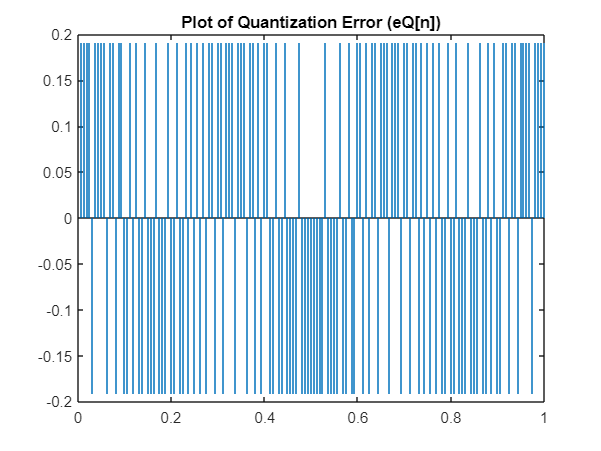

% Define the parameters
amplitude1 = 1;
amplitude3 = 1;
frequency1 = 1;
frequency3 = 3;
quantization_bits = 8;
delta_value = 0.1914;

% Define the time parameters
sampling_frequency = 20;
oversampling_frequency = quantization_bits * sampling_frequency;
time_vector = 0:1/oversampling_frequency:1;  % Create a time vector from 0 to 1 second with the specified sampling rate

% Define the signal x(t)
signal_x = amplitude1 * sin(2 * pi * frequency1 * time_vector) + amplitude3 * sin(2 * pi * frequency3 * time_vector);

% Perform delta modulation
modulated_signal = zeros(size(time_vector));
quantized_signal = zeros(size(time_vector));
quantization_error = zeros(size(time_vector));
quantized_signal(1) = 0;  % Set the initial value of the quantized signal

for n = 2:length(time_vector)
    % Delta modulation
    delta_x = signal_x(n) - quantized_signal(n-1);
    modulated_signal(n) = sign(delta_x);
    quantization_error(n) = delta_value * modulated_signal(n);
    
    % Receiver: Accumulate received quantized error alphabets
    quantized_signal(n) = quantized_signal(n-1) + quantization_error(n);
end

% Calculate the recovered signal
recovered_signal = cumsum(quantization_error);

% Plotting
clf;
stem(time_vector, quantization_error, 'Marker','none');  % Plot the quantized error signal
title("Plot of Quantization Error (eQ[n])");  % Set the title of the plot

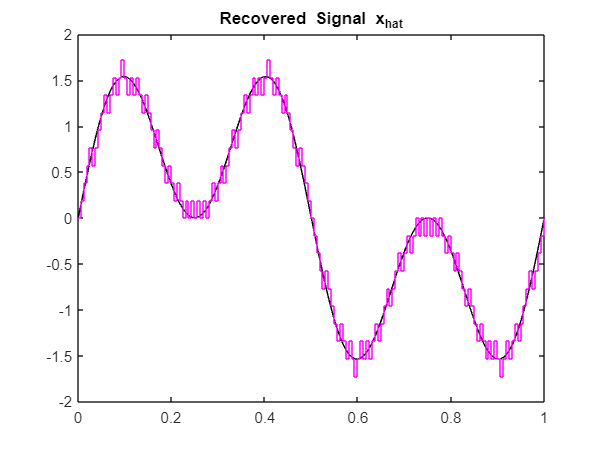

% Plot the original signal x(t) and the recovered signal x_hat
figure;

% Plot the original signal x(t)
plot(time_vector, signal_x, 'k-');
title('Original Signal x(t)');
hold on;

% Plot the recovered signal x_hat
stairs(time_vector, recovered_signal, 'm-');
title('Recovered Signal x_hat');
hold off;

The code designs a lowpass Butterworth filter with a specified cutoff frequency and applies it to the recovered signal x_hat to obtain a smoothed version.

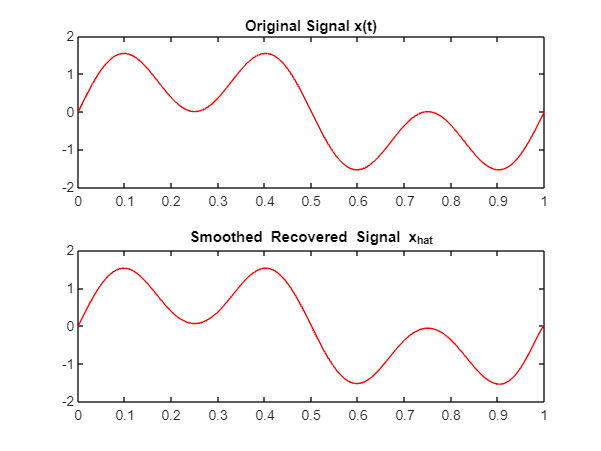

% Design a lowpass filter (Butterworth filter in this example)
cutoff_frequency = 8;  % Adjust as needed
[b, a] = butter(4, cutoff_frequency / (oversampling_frequency/2), 'low');

% Apply the lowpass filter to x_hat
smoothed_x_hat = filtfilt(b, a, recovered_signal);

% Plotting
figure;
subplot(2, 1, 1);
plot(time_vector, signal_x, 'r');
title('Original Signal x(t)');
subplot(2, 1, 2);
plot(time_vector, smoothed_x_hat, 'r');
title('Smoothed Recovered Signal x_hat');

***I will now try predicting values for A = 1.25 and 1.5***

The code initializes given data consisting of amplitudes and corresponding delta values, plots the given data, and then applies a moving average filter to smooth the delta values with a specified window size.

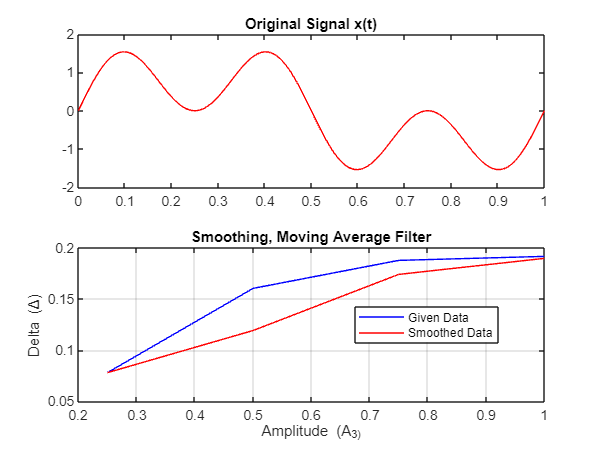

% Given data
amplitudes = [0.25 0.5 0.75 1.00];
delta_values = [0.0781 0.1602 0.1875 0.1914];

% Plotting the given data
plot(amplitudes, delta_values, 'b');
xlabel('Amplitude (A_3)');
ylabel('Delta (\Delta)');
title('Smoothing, Moving Average Filter');
grid on;

% Applying a moving average filter
window_size = 2; % Adjust the window size as needed
smoothed_delta = movmean(delta_values, window_size);

% Plotting the smoothed data
hold on;
plot(amplitudes, smoothed_delta, 'r');
legend('Given Data', 'Smoothed Data', 'Location', 'Best');
hold off;

This segment of code creates a linear interpolation for the smoothed data using the `interp1` function with a specified method ('linear') and then predicts delta values for unknown amplitudes (1.25 and 1.5) based on the smoothed data using the `ppval` function. Finally, it displays the predicted delta values for the unknown points.

% Creating a linear interpolation for smoothed data
smoothed_interp = interp1(amplitudes, smoothed_delta, 'linear', 'pp');

% Predicting values for unknown points
unknown_amplitudes = [1.25, 1.5];
predicted_deltas = ppval(smoothed_interp, unknown_amplitudes);

% Displaying the predicted values
disp('Predicted values for unknown points based on smoothed data:');

Predicted values for unknown points based on smoothed data:


disp(['A_3 = 1.25: Delta = ' num2str(predicted_deltas(1))]);

A_3 = 1.25: Delta = 0.20505


disp(['A_3 = 1.5:  Delta = ' num2str(predicted_deltas(2))]);

A_3 = 1.5:  Delta = 0.22065


#### Analysis and summary for the entire lab: 

The exercise contrasts Delta Modulation (DM) with traditional Pulse Code Modulation (PCM), highlighting DM's simplicity in error quantization and binary output generation compared to PCM's complex sample quantization. DM's oversampling enhances frequency resolution and reduces quantization noise, making it bandwidth-efficient. However, DM is sensitive to rapid signal changes. The FFT plot's amplitude halving reflects the discrete nature of digital signals. Smoothing via low-pass filters improves signal recovery, while interpolation aids in data estimation. Predicting deltas for unknown amplitudes extrapolates system behavior. Understanding these trade-offs is vital for designing efficient digital communication systems

#### Matlab Keyboard Shortcuts (for myself): 

Ctrl + Shift + (numbers)/T = Headings/Subheadings/normal text

F5 = Run all code

Ctrl + enter = Run the code for your section 

Alt + Enter = Insert Text/Code

Ctrl + Alt + Enter = Section Break